# Hilbert-Huang Transform

Author: Mario Paul Tafur Díaz

Contact: mariop.tafur@gmail.com / 71491743@usat.pe

This live script will be the base to set how the hht tool will perform.

The preliminary data was provided by my advisor.

## Visualizing the preliminary data

Plotting the data for a better understanding. It is clear that it has no stationary nor linear behavior.

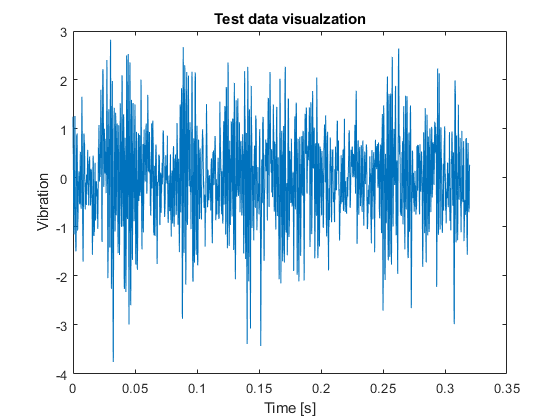

% Importing the data
T = readtable('Test_data.xls');

% Variable asignation
t = T.Var1;
y = T.Var2;

% Creation of figure window
figure;
plot(t,y);
title('Test data visualzation');
xlabel('Time [s]');
ylabel('Vibration');

## Empirical Mode Decomposition

Applying the EMD to the data.

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.067891   |  SiftMaxRelativeTolerance
      2      |        2     |      0.05046   |  SiftMaxRelativeTolerance
      3      |        2     |     0.040253   |  SiftMaxRelativeTolerance
      4      |        3     |     0.049048   |  SiftMaxRelativeTolerance
      5      |        2     |     0.053762   |  SiftMaxRelativeTolerance
      6      |        1     |       0.1596   |  SiftMaxRelativeTolerance
      7      |        2     |     0.023195   |  SiftMaxRelativeTolerance
      8      |        3     |      0.18658   |  SiftMaxRelativeTolerance
      9      |        1     |      0.18484   |  SiftMaxRelativeTolerance
Decomposition stopped because the number of extrema in the residual signal is less than the 'MaxNumExtrema' value.


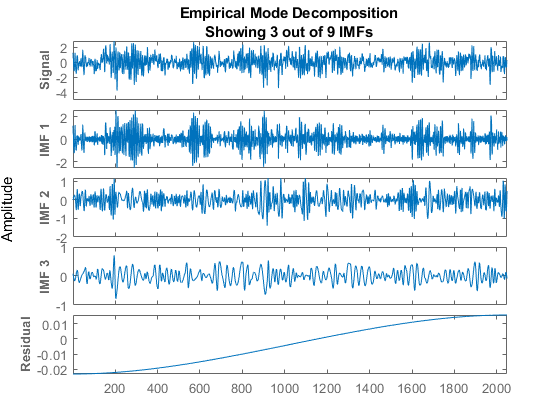

[imf,residual,info] = emd(y,'Interpolation','pchip');       % Saving data of IMFs, residual and aditional info for diagnostic purposes
emd(y,'Interpolation','pchip','Display',1)                  % For visualization purposes

## Hilbert Spectrum Analysis

Here the Hilbert spectrum is obtained from the IMFs.

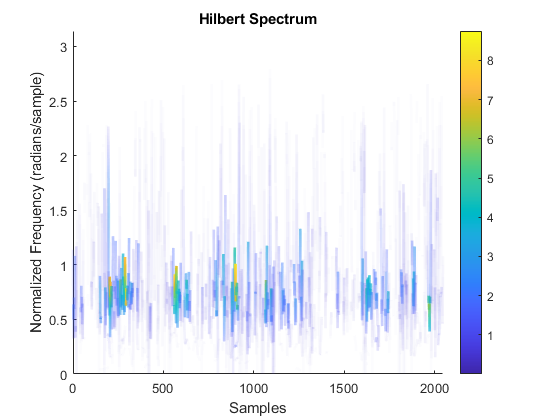

hht(imf)